# **[2024년 1학기 디지털제어 MATLAB/Simulink 예제] Ch. 7-c. 나이퀴스트 선도를 이용한 안정성 판별과 이득/위상 여유**

- 본 파일은 2024년 1학기 개설된 서울시립대학교 전자전기컴퓨터공학부 **디지털제어** 교과목 수업의 보조 자료로 활용하기 위해 제작되었습니다.

- **작성자** : 서울시립대학교 전자전기컴퓨터공학부 박경훈 교수(gyunghoon.park@uos.ac.kr), 김준수 박사과정생

- **교과목 github 페이지 **: [https://github.com/CDSL-UoS/Course_Digital-Control_2024](https://github.com/CDSL-UoS/Course_Digital-Control_2024) 

- **교과목 notion 페이지** : [https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4](https://cdsl-uos-wiki.notion.site/2024-1-40067-01-f2be00650e8f4a3db78b7f464b94be14?pvs=4) 

- **참고사항** : 2023b version 이상의 MATLAB/Simulink 환경에서 구동을 권장합니다. (2023a 이하 version 사용 시 Simulink 파일 등이 원활히 작동되지 않을 수 있습니다.)

아래 예제를 실행하기에 앞서, 다음 코드를 실행하여 작업 공간 등을 초기화합시다.

clc; clear all; close all;      % Initialization

### Topic 1 : 나이퀴스트 선도와 판별법

앞선 실습들과 유사하게, 이번 실습에서는 다음의 연속 시간 플랜트


$$G_p(s)=\frac{0.2}{s^2 + 2s + 2}$$


를 샘플 데이터 제어 환경에서 다음의 이산 시간 제어기


$$C^d(z)=K$$


로 제어하는 상황을 생각해봅시다. 적절한 제어기 이득 $K$를 선정하기 위해, 먼저 연속 시간 플랜트에 대한 펄스 전달함수를 계산합니다.

num_Gp_tf = 0.2;
den_Gp_tf = [1 2 2];
Gp_tf = tf(num_Gp_tf, den_Gp_tf);
T = 0.2;
Gd_tf = c2d(Gp_tf, T, 'zoh')

Gd_tf =
 
  0.003493 z + 0.003057
  ----------------------
  z^2 - 1.605 z + 0.6703
 
샘플 시간: 0.2 seconds
이산시간 전달 함수입니다.
모델 속성


이때 지난 실습에서 전체 폐루프 시스템이 안정할 조건을


$$0<K<107.8584$$


로 얻었는데, 이 조건을 만족하는 $K=15$와 만족하지 않는 $K=150$을 선정하고, 두 경우에 대해 나이퀴스트 안정성 조건이 어떻게 적용되는지를 확인해보고자 합니다.

각 경우에 대한 개루프 전달함수 $L^d(z) = G^d(z) C^d(z)$을 다음과 같이 얻습니다. 

Ld1_tf = 15 * Gd_tf;
Ld2_tf = 150 * Gd_tf;

이제 나이퀴스트 안정성 판별법의 핵심이 되는 다음 수식을 기억해봅시다.


$$N = Z-P$$


여기서 각각의 값은 다음과 같습니다. 

- $N$ : $L^d(e^{j\omega T})$의 나이퀴스트 궤적이 $(-1,0)$을 감싼 횟수 (시계 방향)

- $Z$ :  $1+L^d(z)$의 불안정한 영점(즉, 전체 폐루프 시스템의 불안정한 극점)의 수

- $P$ : $L^d(z)$의 불안정한 극점의 수

따라서 


$$Z=P+N$$


이 0이라면 폐루프 시스템은 안정하다고 결론지을 수 있습니다. 

두 경우 모두 $L^d(z)$가 안정하므로, $P=0$입니다.

pole(Ld1_tf)

ans =    0.8024 + 0.1627i
   0.8024 - 0.1627i


따라서 $N$이 0이면 전체 폐루프 시스템이 안정한데,  `nyquistplot` 함수를 이용하여 두 개루프 전달함수의 나이퀴스트 선도를 그려서 확인할 수 있습니다.

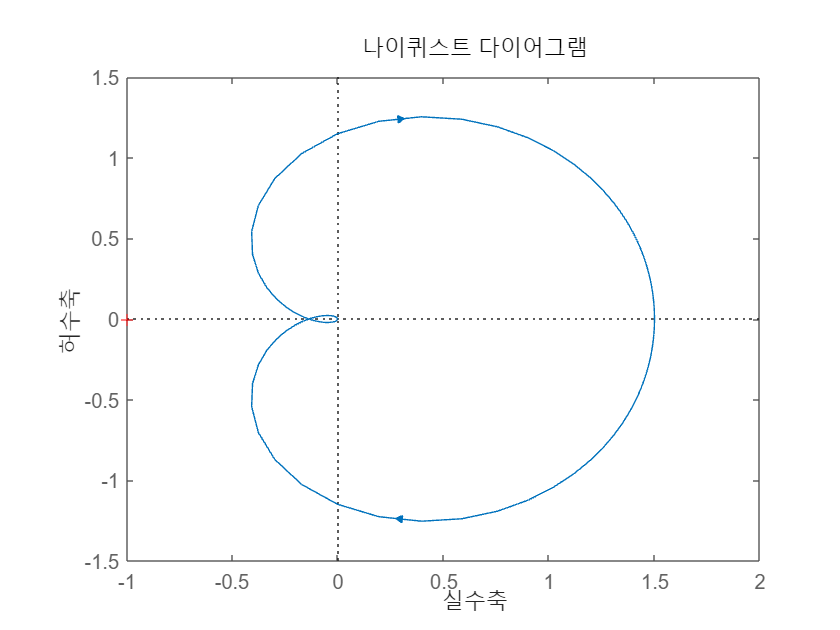

figure();
nyquistplot(Ld1_tf)

$L_1^d(z) = 15 G^d(z)$의 경우, 나이퀴스트 궤적이 $(-1,0)$을 감싸지 않고 있으므로, $N=0$입니다.

하지만 아래에서처럼 $L_2^d(z) = 150 G^d(z)$의 경우, 나이퀴스트 궤적이 $(-1,0)$을 1번 감싸기 때문에, $N=1$이 되어 전체 폐루프 시스템이 불안정하게 됩니다. 

(nyquistplot 함수의 결과를 변수로 지정하면, zoomcp 함수를 추가로 이용하여 $(-1,0)$ 주변을 확대해볼 수도 있습니다.)

figure();
h = nyquistplot(Ld2_tf)


h =

	resppack.nyquistplot



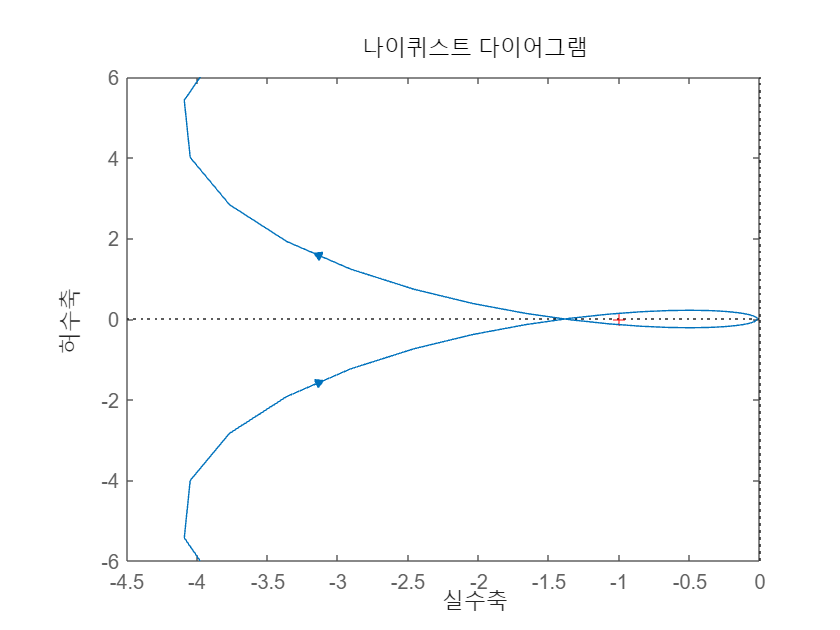

zoomcp(h)

한편 $N$은 쌍선형 변환(bilinear transformation)로 변환된 ${\rm w}$-영역에서 나이퀴스트 선도를 그림으로써도 확인할 수 있습니다. 

보다 자세히 말하면, 쌍선형 변환이 개념적으로 $z$-영역의 단위원을 허수축으로 변환하는 방법이기 때문에, 쌍선형 변환으로 얻은 ${\rm w}$-영역에서의 전달함수의 나이퀴스트 선도는 기존 $z$-영역에서의 전달함수의 나이퀴스트 선도와 사실상 동일합니다.

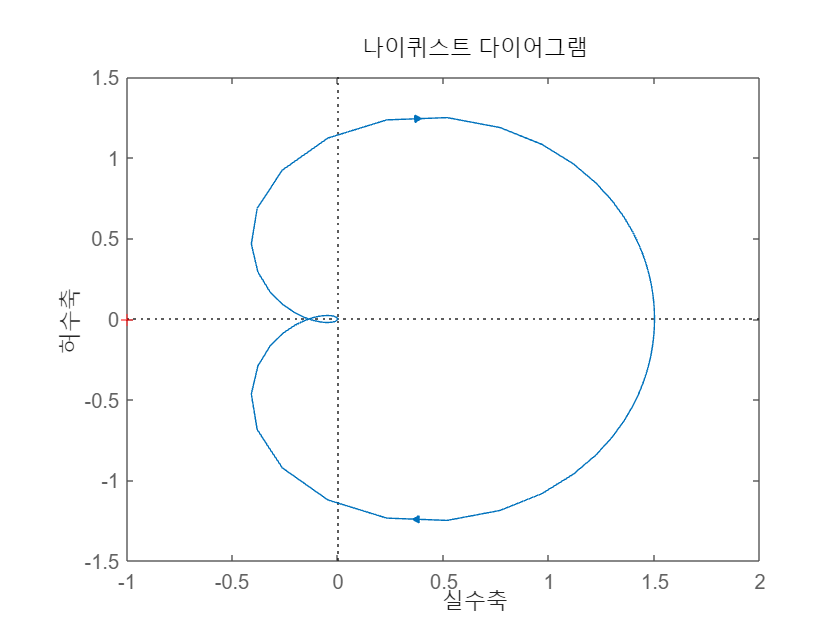

Lw1_tf = d2c(Ld1_tf, 'tustin');
figure();
nyquist(Lw1_tf)

### Topic 2 : 이득/위상 여유

개념적으로는 나이퀴스트 선도를 통해서 이득 여유(gain margin), 위상 여유(phase margin) 등을 계산할 수 있지만, MATLAB에서는 `margin` 함수를 이용하여 수치적으로 그 값을 찾을 수 있습니다.

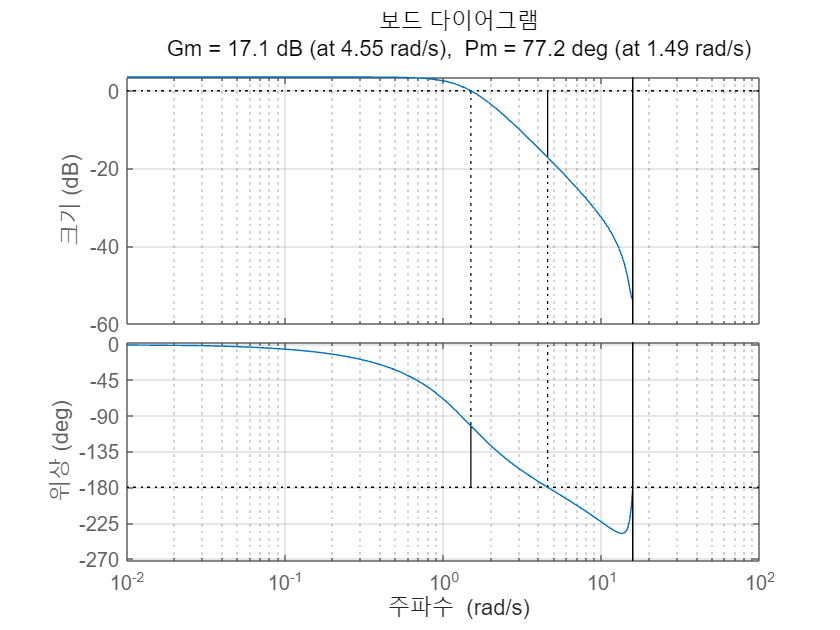

figure();
margin(Ld1_tf); grid on;

여기서 Gm은 이득 여유, Pm은 위상 여유를 의미하며, 이 값들은 아래와 같이 `margin` 함수의 출력으로도 얻을 수 있습니다. 

[Gm,Pm,Wcg,Wcp] = margin(Ld1_tf)

Gm = 7.1905

Pm = 77.2212

Wcg = 4.5483

Wcp = 1.4903

이제 이득 여유와 위상 여유의 개념을, 조금 더 시각적으로 살펴보도록 하겠습니다. 

먼저 이득 여유는, 기존의 개루프 전달함수 $L_1^d(z)$에 상수 ${\rm GM}$을 곱하여 얻은 ${\rm GM}\cdot L_1^d(z)$의 나이퀴스트 궤적이 $(-1,0)$을 만나도록 하는 상수 ${\rm GM}$의 값을 의미합니다. 

이를 확인해보기 위해, 위에서 구한 Gm 값을 곱한 ${\rm GM}\cdot L_1^d(z)$의 나이퀴스트 선도를 추가로 그리면 다음을 얻습니다. 

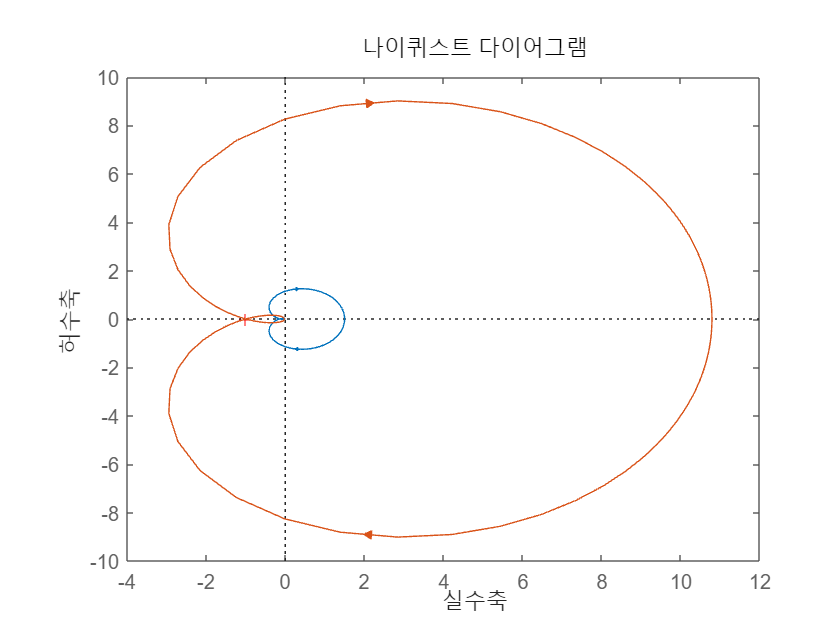

figure();
nyquist(Ld1_tf)
hold on;
nyquist(Ld1_tf * Gm)

한편 위상 여유는, 기존의 개루프 전달함수 $L_1^d(z)$에 복소수 $e^{-j({\rm PM})}$을 곱하여 얻은 $L_1^d(z)e^{-j({\rm PM})}$의 나이퀴스트 궤적이 $(-1,0)$을 만나도록 하는 ${\rm PM}$의 값을 의미합니다. 

이를 유사하게 그려보면 다음과 같습니다. 

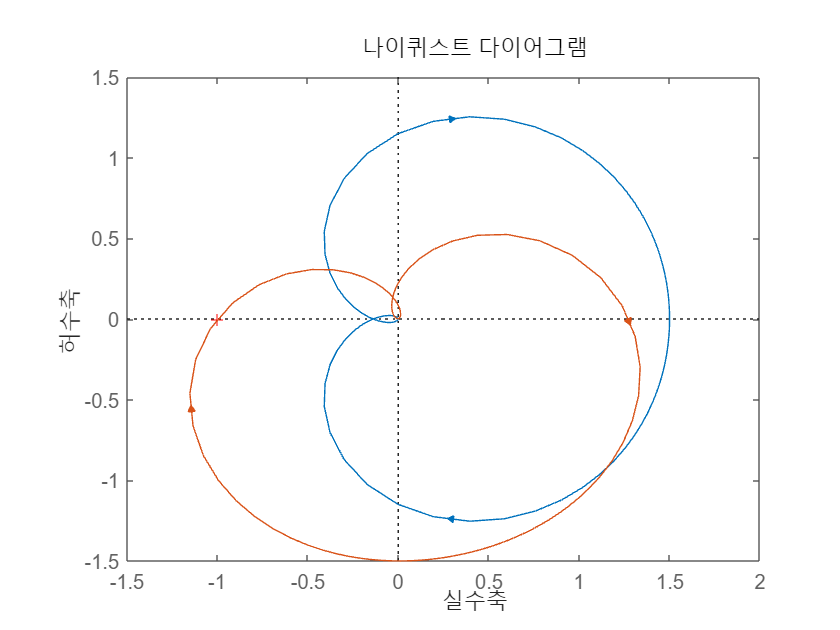

figure();
nyquist(Ld1_tf)
hold on;
nyquist(Ld1_tf * exp((1i)*deg2rad(-Pm)))

앞에서 소개한  ${\rm GM}\cdot L_1^d(z)$ 혹은 $L_1^d(z)e^{-j({\rm PM})}$는 모든 여유를 다 소모하였기 때문에, 추가적인 여유가 거의 없게 됩니다. 

예시로 `margin` 함수를 이용하여 $L_1^d(z)e^{-j({\rm PM})}$에 대해 다시 이득 여유와 위상 여유를 계산해보면 다음과 같이 매우 작은 값을 얻게 됩니다.

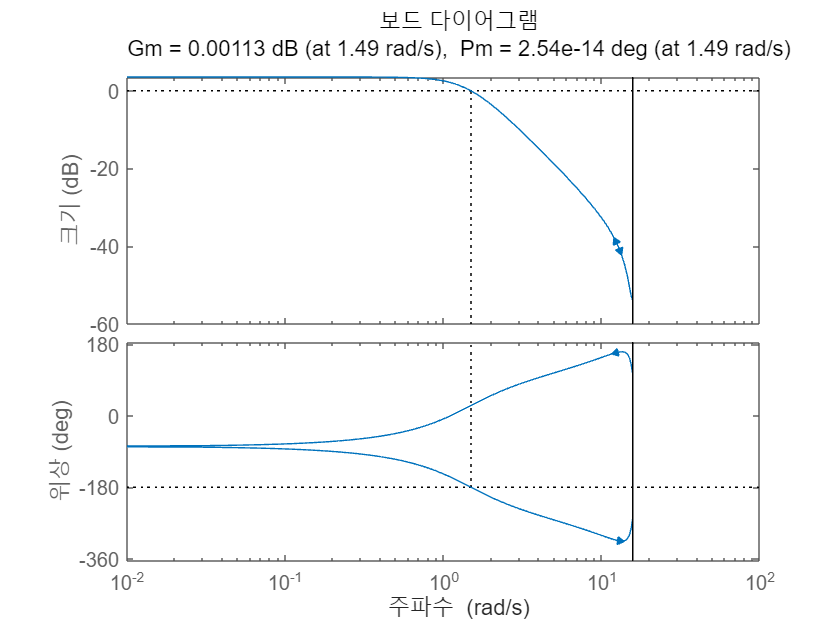

figure();
margin(Ld1_tf * exp((1i)*deg2rad(-Pm)))